# QEA 2 Robo Homework 6

**By Ari Porad, April 25th, 2021**

## Exercise 27.1

## 27.1.2

p = [2 -1]

p =      2    -1


theta = pi / 3;
R = [cos(theta), sin(theta); -sin(theta), cos(theta)]

R =     0.5000    0.8660
   -0.8660    0.5000



R * p'

ans =     0.1340
   -2.2321



inv(R) * [3;-2]

ans =     3.2321
    1.5981


## 27.2

r1g = [2 -1 1]'

r1g =      2
    -1
     1


theta = pi / 3;
R = [cos(theta), sin(theta), 0; -sin(theta), cos(theta), 0; 0, 0, 1]

R =     0.5000    0.8660         0
   -0.8660    0.5000         0
         0         0    1.0000


T = [1, 0, 3; 0, 1, -1; 0, 0, 1]

T =      1     0     3
     0     1    -1
     0     0     1



r1m = R * T * r1g

r1m =     0.7679
   -5.3301
    1.0000



r2m = [3 -2 1]'

r2m =      3
    -2
     1


r2g = inv(T) * inv(R) * r2m

r2g =     0.2321
    2.5981
    1.0000


ans =     0.2321    2.5981    1.0000


## Exercise 27.4

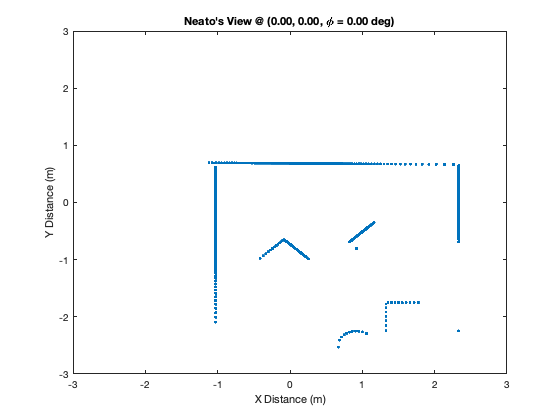

load('lidar.mat', 'theta_all', 'r_all');

r1g = plot_helper(r_all(:, 1), theta_all(:, 1), [0, 0], 0);

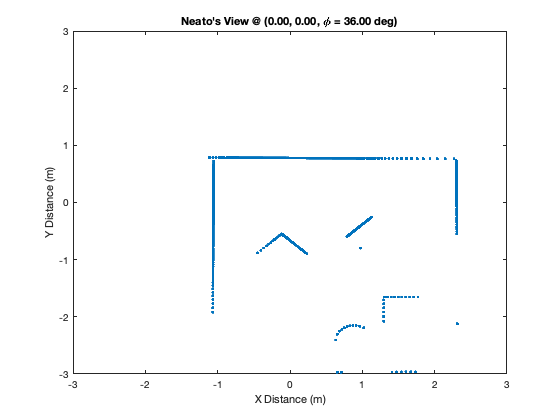

r2g = plot_helper(r_all(:, 2), theta_all(:, 2), [0, 0], pi/5);

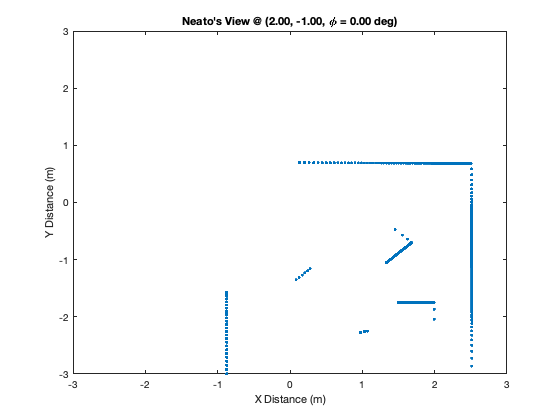

r3g = plot_helper(r_all(:, 3), theta_all(:, 3), [2, -1], 0);

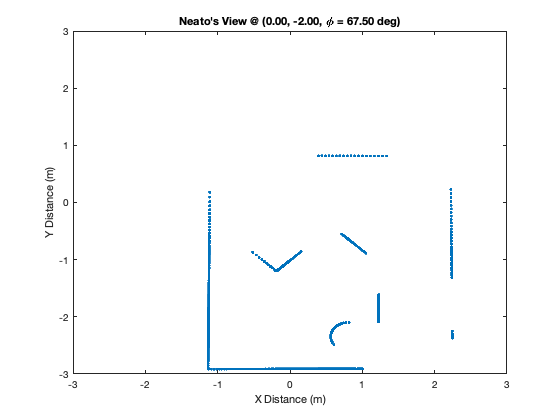

r4g = plot_helper(r_all(:, 4), theta_all(:, 4), [0, -2], (3*pi) / 8);

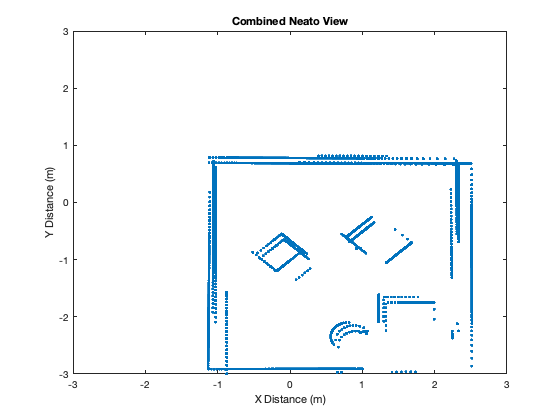


rallg = [r1g; r2g; r3g; r4g];

figure;
plot(rallg(:, 1), rallg(:, 2), '.');
title("Combined Neato View");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
ylim([-3, 3]);
xlim([-3, 3]);

function r_G = to_global(R, theta, origin, phi)
    [X_raw, Y_raw] = pol2cart(theta, R);
    r_L = [X_raw, Y_raw, ones(length(X_raw), 1)]';
    r_N = [1, 0, 0.084; 0, 1, 0; 0, 0, 1] * r_L; % no rotation needed
    r_G_raw = [1, 0, origin(1); 0, 1, origin(2); 0, 0, 1] * [cos(phi), -sin(phi), 0; sin(phi), cos(phi), 0; 0, 0, 1] * r_N;
    r_G = r_G_raw(1:2, :)';
end

function r_G = plot_helper(R, theta, origin, phi, desc)
    if nargin < 5
        desc = "Neato's View";
    end

    r_G = to_global(R, theta, origin, phi);
    
    figure;
    plot(r_G(:, 1), r_G(:, 2), '.');
    title(sprintf("%s @ (%1.2f, %1.2f, \\phi = %1.2f deg)", ...
        desc, origin(1), origin(2), rad2deg(phi)));
    xlabel("X Distance (m)");
    ylabel("Y Distance (m)");
    ylim([-3, 3]);
    xlim([-3, 3]);
end